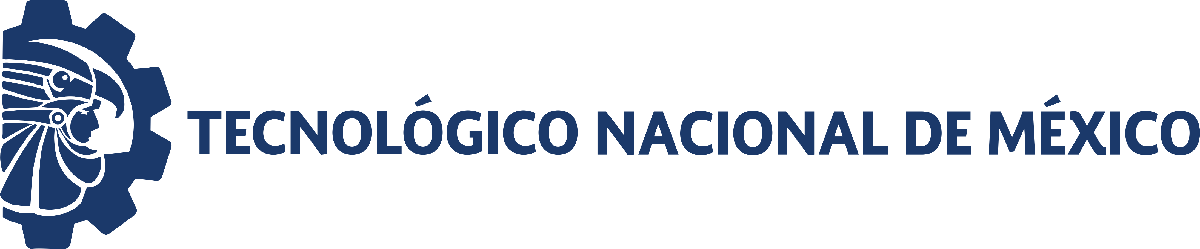                                 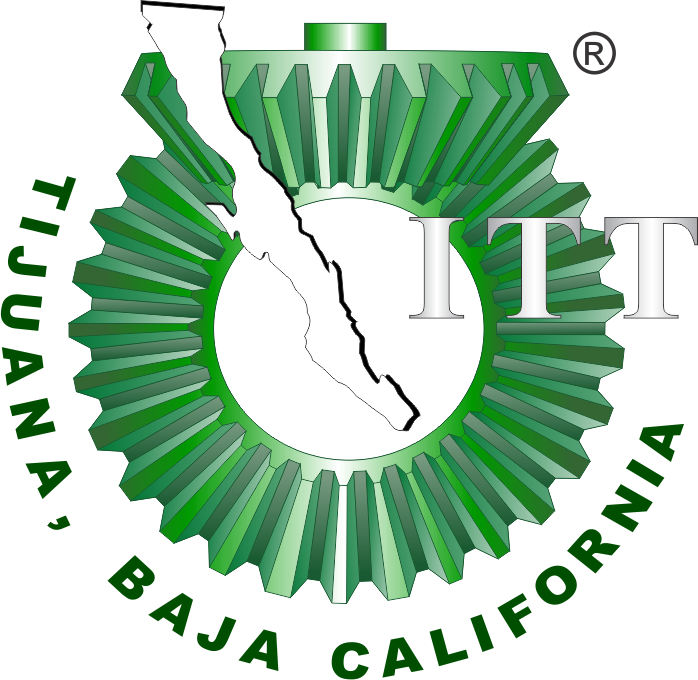

# Práctica uno: Diseño de controlador para un sistema de segudo orden

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[Foto]

Nombre del alumno: Jesus Javier Morales Lozoya

Número de control: 20210806

Correo institucional: **jesus.moralesl201@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Practica_1m';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';

## Respuesta al escalón

signal= 'Step';
set_param('Practica_1m/S1','sw','1');
set_param('Practica_1m/Ve(t)','sw','1');
x1 = sim(file,parameters);

Found algebraic loop that contains: 
Practica_1m/Vs3(t)/1//3R
Practica_1m/Vs3(t)/R
Practica_1m/Vs3(t)/L
Practica_1m/Vs3(t)/d[i1(t)-i2(t)]//dt
Practica_1m/Vs3(t)/Add
Practica_1m/Vs3(t)/1//2R
Practica_1m/Vs3(t)/R1
Practica_1m/Vs3(t)/Add2 (algebraic variable)


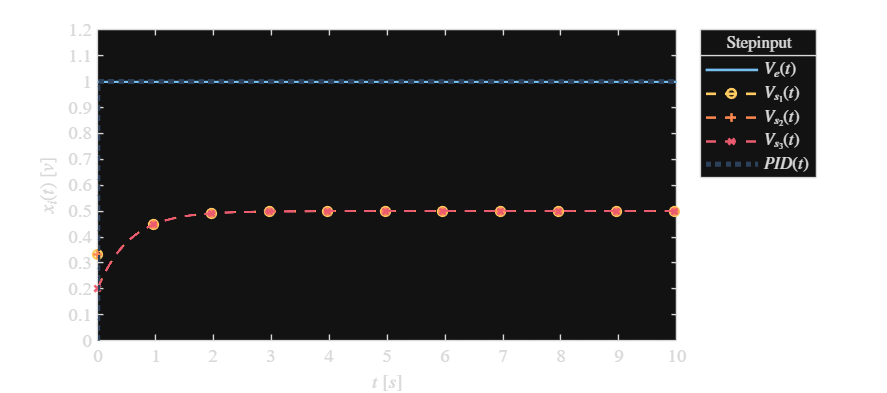

plotsignals(x1.tout,x1.Ve,x1.Vs1,x1.Vs2,x1.Vs3,x1.PID,signal)

## Respuesta al impulso

signal= 'Impulse';
set_param('Practica_1m/S1','sw','0');
set_param('Practica_1m/Ve(t)','sw','1');
x2 = sim(file,parameters);

Found algebraic loop that contains: 
Practica_1m/Vs3(t)/1//3R
Practica_1m/Vs3(t)/R
Practica_1m/Vs3(t)/L
Practica_1m/Vs3(t)/d[i1(t)-i2(t)]//dt
Practica_1m/Vs3(t)/Add
Practica_1m/Vs3(t)/1//2R
Practica_1m/Vs3(t)/R1
Practica_1m/Vs3(t)/Add2 (algebraic variable)


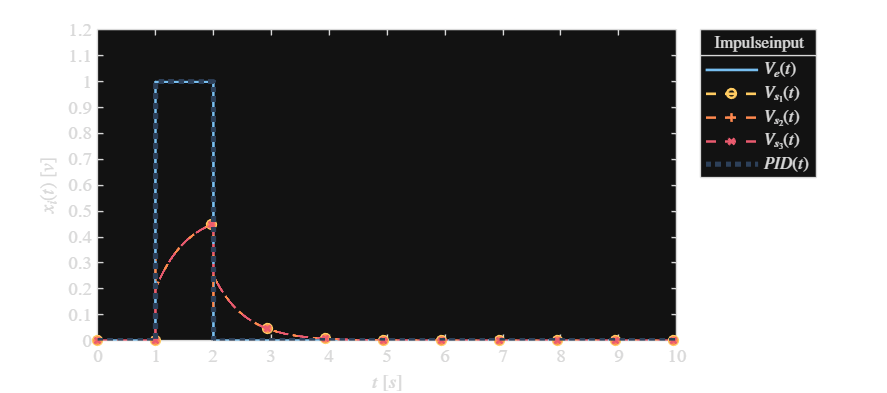

plotsignals(x2.tout,x2.Ve,x2.Vs1,x2.Vs2,x2.Vs3,x2.PID,signal)

## Respuesta a la rampa

signal= 'Ramp';
set_param('Practica_1m/S2','sw','1');
set_param('Practica_1m/Ve(t)','sw','0');
x3 = sim(file,parameters);

Found algebraic loop that contains: 
Practica_1m/Vs3(t)/1//3R
Practica_1m/Vs3(t)/R
Practica_1m/Vs3(t)/L
Practica_1m/Vs3(t)/d[i1(t)-i2(t)]//dt
Practica_1m/Vs3(t)/Add
Practica_1m/Vs3(t)/1//2R
Practica_1m/Vs3(t)/R1
Practica_1m/Vs3(t)/Add2 (algebraic variable)


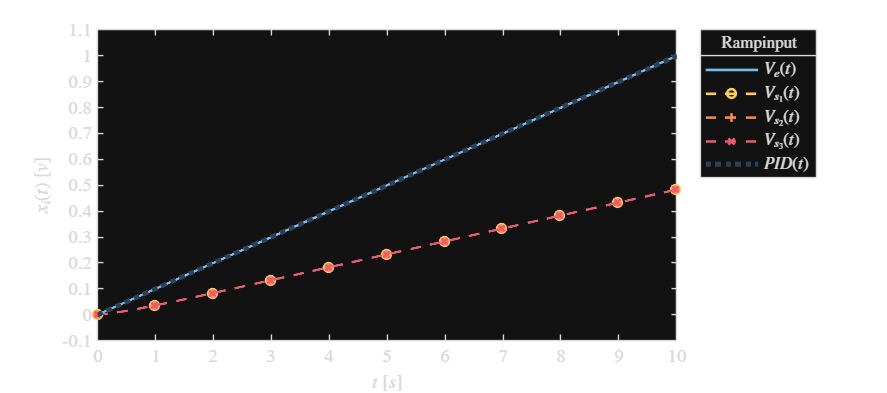

plotsignals(x3.tout,x3.Ve,x3.Vs1,x3.Vs2,x3.Vs3,x3.PID,signal)

## Respuesta a la función sinusoidal

signal= 'Sin';
set_param('Practica_1m/S2','sw','0');
set_param('Practica_1m/Ve(t)','sw','0');
x4 = sim(file,parameters);

Found algebraic loop that contains: 
Practica_1m/Vs3(t)/1//3R
Practica_1m/Vs3(t)/R
Practica_1m/Vs3(t)/L
Practica_1m/Vs3(t)/d[i1(t)-i2(t)]//dt
Practica_1m/Vs3(t)/Add
Practica_1m/Vs3(t)/1//2R
Practica_1m/Vs3(t)/R1
Practica_1m/Vs3(t)/Add2 (algebraic variable)


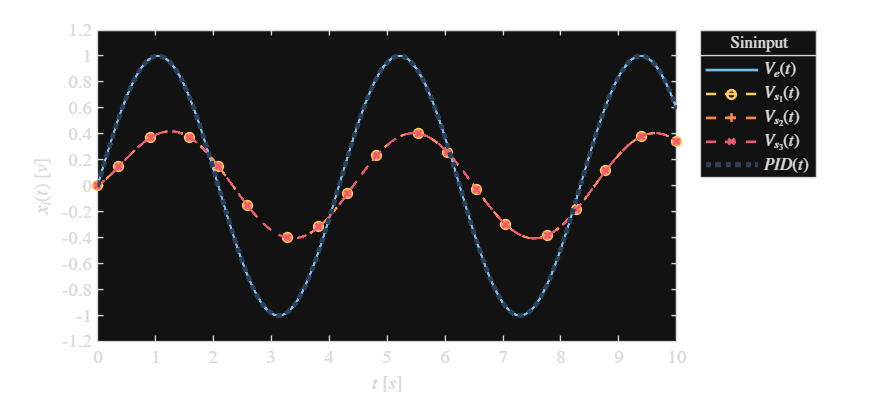

plotsignals(x4.tout,x4.Ve,x4.Vs1,x4.Vs2,x4.Vs3,x4.PID,signal)

 **Función: Respuesta a las señales **

function plotsignals(tout,Ve,Vs1,Vs2,Vs3,PID,Signal)
   set(figure(),'Color','w')
   set(gcf,'units','centimeters','position',[1,1,18,8])
   set(gca,'FontName','Times New Roman','FontSize',11)
   hold on; grid off; box on;
   mycolors =  [119,190,240;
                255,203,97;
                255,137,79;
                234,91,111;
                45,64,89;
                6,66,50]/255;
   colororder(mycolors)

   

   p=plot(tout,Ve,'-',tout,Vs1,'--O',tout,Vs2,'--+',tout,Vs3,'--x',tout,PID,':', ...
       'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(tout));
   set(p(5),'LineWidth',3);
   L = legend('$V_e(t)$','$V_{s_1}(t)$','$V_{s_2}(t)$','$V_{s_3}(t)$','$PID(t)$');
   set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','on');
   title(L,[Signal,'input'],'FontSize',10)

   xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
   ylabel('$x_i(t)$ $[v]$','Interpreter','Latex','FontSize',11)

   xlim([0,10]); xticks(0:1:10);
   if Signal == "Step" || Signal == "Impulse" 
       
       ylim([0,1.2]); yticks(0:0.1:1.2);
   elseif Signal == "Ramp" 
       ylim([-0.1,1.1]); yticks(-0.1:0.1:1.1);
   elseif Signal == "Sin" 
       ylim([-1.2,1.2]); yticks(-1.2:0.2:2);

   end
   exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
   exportgraphics(gcf,[Signal,'.png'],'ContentType','vector')

end
